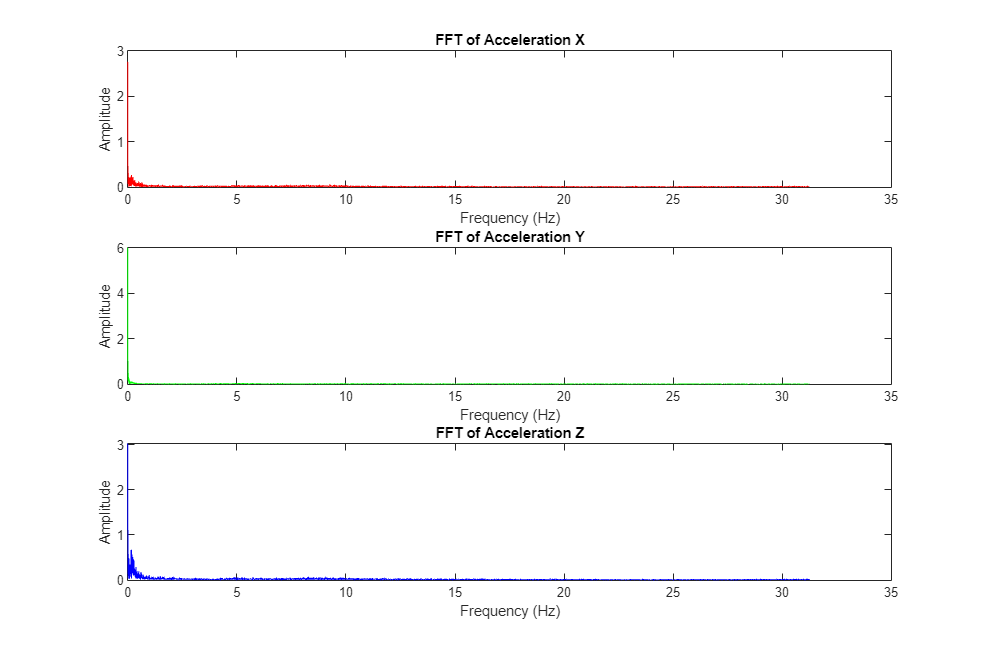

clear; % Elimina todas las variables del espacio de trabajo.
close all; % Cierra todas las figuras abiertas.
clc; % Limpia la ventana de comandos.

addpath('Quaternions'); % Añade la carpeta "Quaternions" al path de MATLAB.
addpath('ximu_matlab_library'); % Añade la carpeta "ximu_matlab_library" al path de MATLAB.

% Load JSON data
filePath = 'C:\Users\Joho_\Desktop\semestreN\sensores y actuadores\practica2\cars.json';
%data = jsondecode(fileread(filePath));

% -------------------------------------------------------------------------
% Importación de datos desde JSON
jsonData = jsondecode(fileread(filePath)); % Lee y decodifica el archivo JSON.
values = jsonData.payload.values; % Extrae los valores de los sensores.
sensors = jsonData.payload.sensors; % Extrae la información de los sensores.
samplePeriod = jsonData.payload.interval_ms / 1000; % Calcula el periodo de muestreo en segundos.

% Mapeo de columnas basado en los nombres de los sensores
accX = values(:, strcmp({sensors.name}, 'accX')); % Datos del acelerómetro en X.
accY = values(:, strcmp({sensors.name}, 'accY')); % Datos del acelerómetro en Y.
accZ = values(:, strcmp({sensors.name}, 'accZ')); % Datos del acelerómetro en Z.
gyrX = values(:, strcmp({sensors.name}, 'gyroX')); % Datos del giroscopio en X.
gyrY = values(:, strcmp({sensors.name}, 'gyroY')); % Datos del giroscopio en Y.
gyrZ = values(:, strcmp({sensors.name}, 'gyroZ')); % Datos del giroscopio en Z.
time = (0:size(values, 1)-1)' * samplePeriod; % Genera el vector de tiempo según la duración de la muestra.

% -------------------------------------------------------------------------
% Selección manual de datos por tiempo
startTime = 6; % Tiempo de inicio en segundos.
stopTime = 240; % Tiempo de finalización en segundos.
indexSel = find(time >= startTime, 1) : find(time <= stopTime, 1, 'last'); % Encuentra índices correspondientes al rango de tiempo seleccionado.
time = time(indexSel); % Filtra el tiempo.
gyrX = gyrX(indexSel, :); % Filtra datos del giroscopio en X.
gyrY = gyrY(indexSel, :); % Filtra datos del giroscopio en Y.
gyrZ = gyrZ(indexSel, :); % Filtra datos del giroscopio en Z.
accX = accX(indexSel, :); % Filtra datos del acelerómetro en X.
accY = accY(indexSel, :); % Filtra datos del acelerómetro en Y.
accZ = accZ(indexSel, :); % Filtra datos del acelerómetro en Z.

% -------------------------------------------------------------------------
% Análisis de Fourier de las aceleraciones
n = length(time); % Número de muestras.
frequencies = (0:n-1)*(1/(samplePeriod*n)); % Vector de frecuencias.
freqLimit = frequencies(1:floor(n/2)); % Solo frecuencias positivas.

accX_fft = abs(fft(accX)/n); % FFT del acelerómetro X.
accY_fft = abs(fft(accY)/n); % FFT del acelerómetro Y.
accZ_fft = abs(fft(accZ)/n); % FFT del acelerómetro Z.

figure('Position', [30 60 900 600], 'NumberTitle', 'off', 'Name', 'Fourier Analysis of Accelerations');
subplot(3,1,1);
plot(freqLimit, accX_fft(1:floor(n/2)), 'r');
title('FFT of Acceleration X');
xlabel('Frequency (Hz)');
ylabel('Amplitude');

subplot(3,1,2);
plot(freqLimit, accY_fft(1:floor(n/2)), 'g');
title('FFT of Acceleration Y');
xlabel('Frequency (Hz)');
ylabel('Amplitude');

subplot(3,1,3);
plot(freqLimit, accZ_fft(1:floor(n/2)), 'b');
title('FFT of Acceleration Z');
xlabel('Frequency (Hz)');
ylabel('Amplitude');

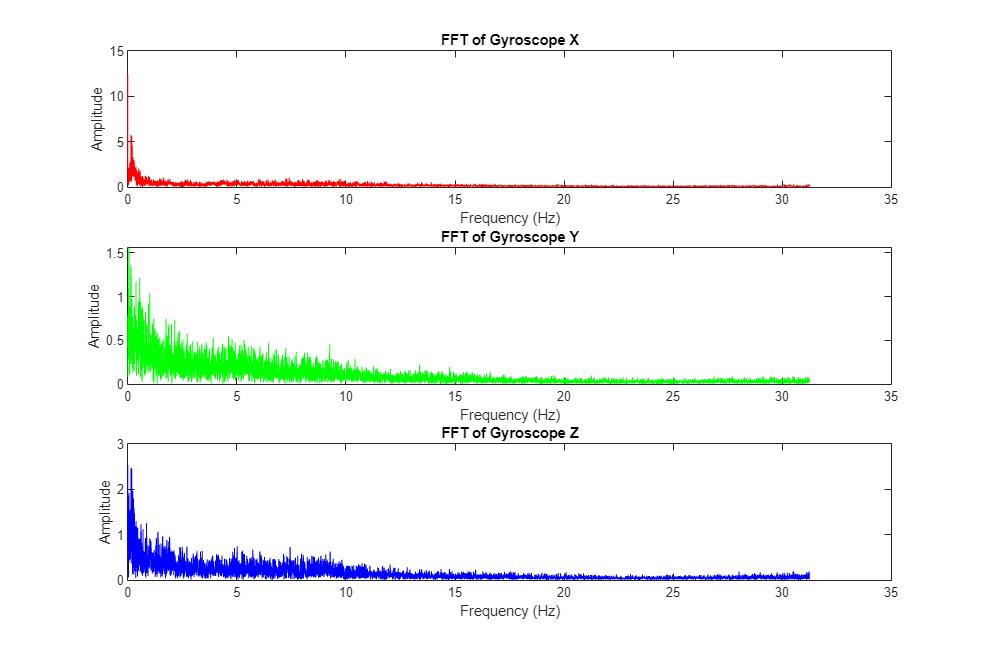

% -------------------------------------------------------------------------
% Análisis de Fourier de los giroscopios
gyrX_fft = abs(fft(gyrX)/n); % FFT del giroscopio X.
gyrY_fft = abs(fft(gyrY)/n); % FFT del giroscopio Y.
gyrZ_fft = abs(fft(gyrZ)/n); % FFT del giroscopio Z.

figure('Position', [30 60 900 600], 'NumberTitle', 'off', 'Name', 'Fourier Analysis of Gyroscope Data');
subplot(3,1,1);
plot(freqLimit, gyrX_fft(1:floor(n/2)), 'r');
title('FFT of Gyroscope X');
xlabel('Frequency (Hz)');
ylabel('Amplitude');

subplot(3,1,2);
plot(freqLimit, gyrY_fft(1:floor(n/2)), 'g');
title('FFT of Gyroscope Y');
xlabel('Frequency (Hz)');
ylabel('Amplitude');

subplot(3,1,3);
plot(freqLimit, gyrZ_fft(1:floor(n/2)), 'b');
title('FFT of Gyroscope Z');
xlabel('Frequency (Hz)');
ylabel('Amplitude');


% Determinar la frecuencia dominante
[~, idxX] = max(accX_fft(1:floor(n/2)))

idxX = 1

[~, idxY] = max(accY_fft(1:floor(n/2)))

idxY = 1

[~, idxZ] = max(accZ_fft(1:floor(n/2)))

idxZ = 2

dominantFreqX = freqLimit(idxX)

dominantFreqX = 0

dominantFreqY = freqLimit(idxY)

dominantFreqY = 0

dominantFreqZ = freqLimit(idxZ)

dominantFreqZ = 0.0043


% -------------------------------------------------------------------------
% Determinar la frecuencia dominante del giroscopio
[~, idxGX] = max(gyrX_fft(1:floor(n/2)));
[~, idxGY] = max(gyrY_fft(1:floor(n/2)));
[~, idxGZ] = max(gyrZ_fft(1:floor(n/2)));
dominantFreqGX = freqLimit(idxGX)

dominantFreqGX = 0

dominantFreqGY = freqLimit(idxGY)

dominantFreqGY = 0.0556

dominantFreqGZ = freqLimit(idxGZ)

dominantFreqGZ = 0

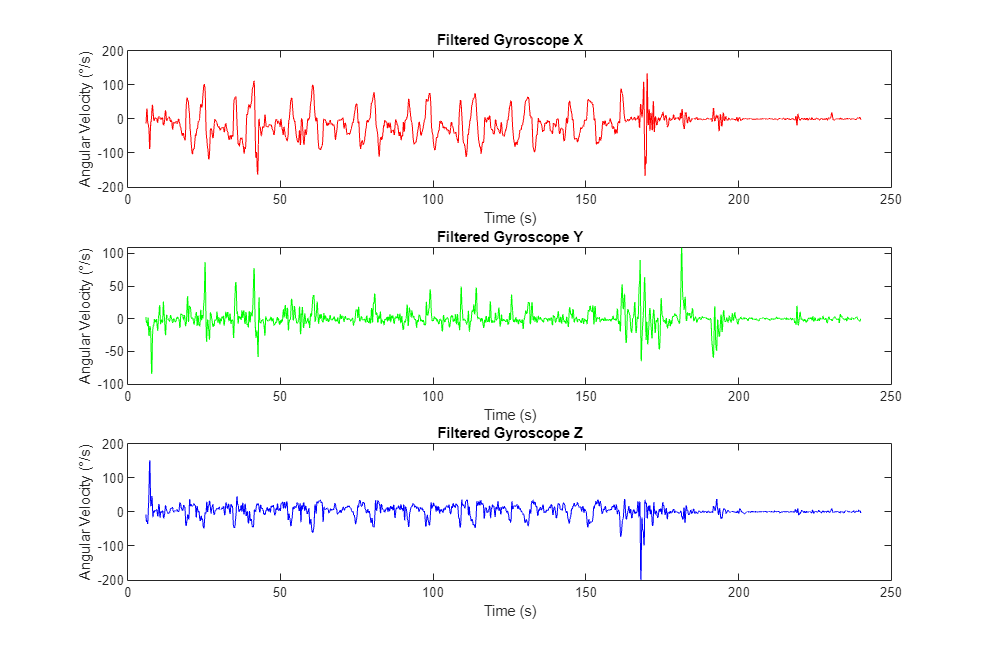


% -------------------------------------------------------------------------
% Filtrado basado en la frecuencia dominante del giroscopio


% Diseño de filtro pasa-banda
[bGX, aGX] = butter(2, dominantFreqGY);
[bGY, aGY] = butter(2, dominantFreqGY);
[bGZ, aGZ] = butter(2, dominantFreqGY);

% Aplicar filtro a las señales del giroscopio
gyrX_filtered = filtfilt(bGX, aGX, gyrX);
gyrY_filtered = filtfilt(bGY, aGY, gyrY);
gyrZ_filtered = filtfilt(bGZ, aGZ, gyrZ);

% Graficar señales filtradas del giroscopio
figure('Position', [40 70 900 600], 'NumberTitle', 'off', 'Name', 'Filtered Gyroscope Data');
subplot(3,1,1);
plot(time, gyrX_filtered, 'r');
title('Filtered Gyroscope X');
xlabel('Time (s)');
ylabel('Angular Velocity (°/s)');

subplot(3,1,2);
plot(time, gyrY_filtered, 'g');
title('Filtered Gyroscope Y');
xlabel('Time (s)');
ylabel('Angular Velocity (°/s)');

subplot(3,1,3);
plot(time, gyrZ_filtered, 'b');
title('Filtered Gyroscope Z');
xlabel('Time (s)');
ylabel('Angular Velocity (°/s)');

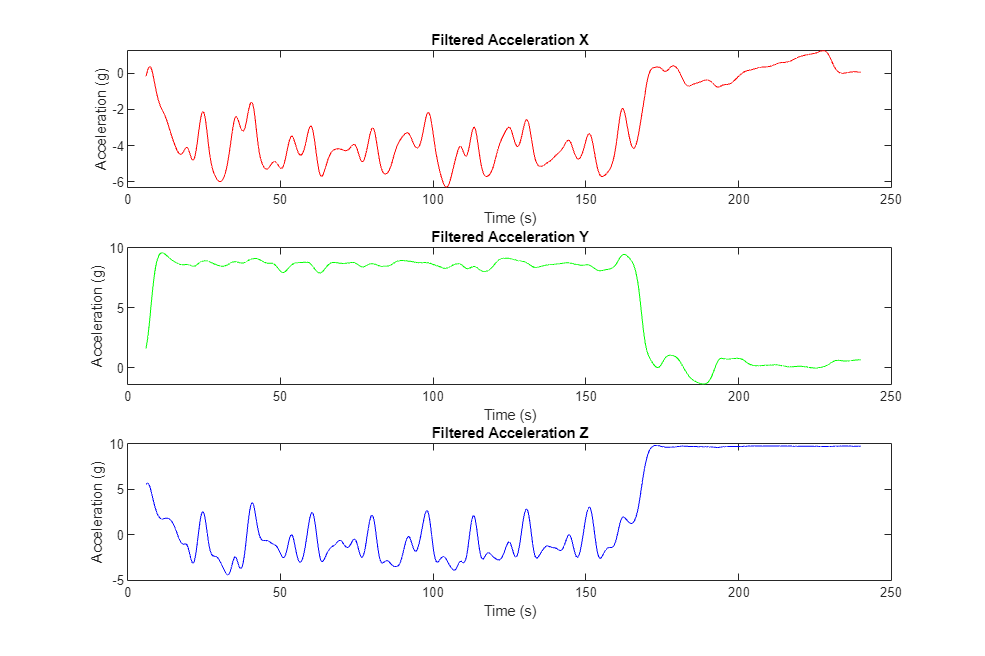


% -------------------------------------------------------------------------
% Filtrado basado en la frecuencia dominante
filterBandwidth = 2; % Ancho de banda para el filtro pasa-banda (Hz).
nyquistFreq = 1 / (2 * samplePeriod); % Frecuencia de Nyquist.

% Diseño de filtro pasa-banda
[bX, aX] = butter(2, dominantFreqZ);
[bY, aY] = butter(2, dominantFreqZ);
[bZ, aZ] = butter(2, dominantFreqZ);

% Aplicar filtro a las señales
accX_filtered = filtfilt(bX, aX, accX);
accY_filtered = filtfilt(bY, aY, accY);
accZ_filtered = filtfilt(bZ, aZ, accZ);

% Graficar señales filtradas
figure('Position', [40 70 900 600], 'NumberTitle', 'off', 'Name', 'Filtered Accelerations');
subplot(3,1,1);
plot(time, accX_filtered, 'r');
title('Filtered Acceleration X');
xlabel('Time (s)');
ylabel('Acceleration (g)');

subplot(3,1,2);
plot(time, accY_filtered, 'g');
title('Filtered Acceleration Y');
xlabel('Time (s)');
ylabel('Acceleration (g)');

subplot(3,1,3);
plot(time, accZ_filtered, 'b');
title('Filtered Acceleration Z');
xlabel('Time (s)');
ylabel('Acceleration (g)');

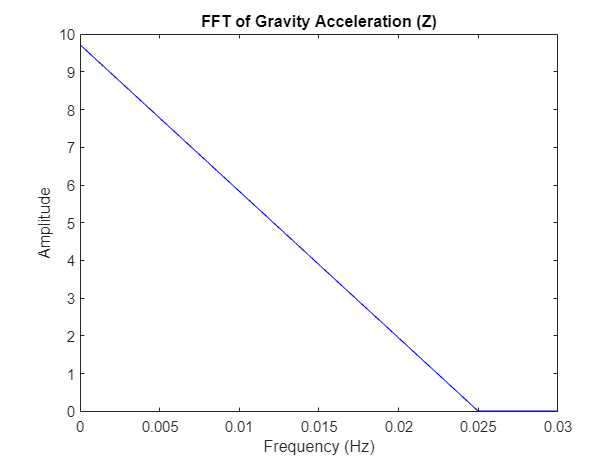

% Seleccionar datos a partir de los 200 segundos
time_gravity = time(time >= 200); % Tiempo mayor a 200 segundos
accZ_gravity = accZ_filtered(time >= 200); % Datos de accZ_filtered a partir de 200 segundos

% Calcular FFT de los datos seleccionados
n = length(accZ_gravity); % Número de muestras
frequencies = (0:n-1) * (1 / (samplePeriod * n)); % Vector de frecuencias
freqLimit = frequencies(1:floor(n/2)); % Solo frecuencias positivas

accZ_fft = abs(fft(accZ_gravity) / n); % FFT de los datos de gravedad

% Graficar el espectro de frecuencias
figure;
plot(freqLimit, accZ_fft(1:floor(n/2)), 'b');
title('FFT of Gravity Acceleration (Z)');
xlabel('Frequency (Hz)');
ylabel('Amplitude');
xlim([0 0.03]); % Limitar el eje X de 0 a 1 Hz


% Identificar la frecuencia más baja que no sea 0
threshold = 1e-6; % Umbral mínimo para considerar amplitudes significativas
validIndices = find(accZ_fft(1:floor(n/2)) > threshold); % Índices con amplitudes significativas
lowestFreqIdx = validIndices(1); % Índice de la frecuencia más baja significativa
lowestFreq = freqLimit(lowestFreqIdx); % Frecuencia correspondiente

% Mostrar la frecuencia más baja con 4 decimales
fprintf('Frecuencia más baja significativa asociada a la gravedad: %.4f Hz\n', lowestFreq);

Frecuencia más baja significativa asociada a la gravedad: 0.0000 Hz


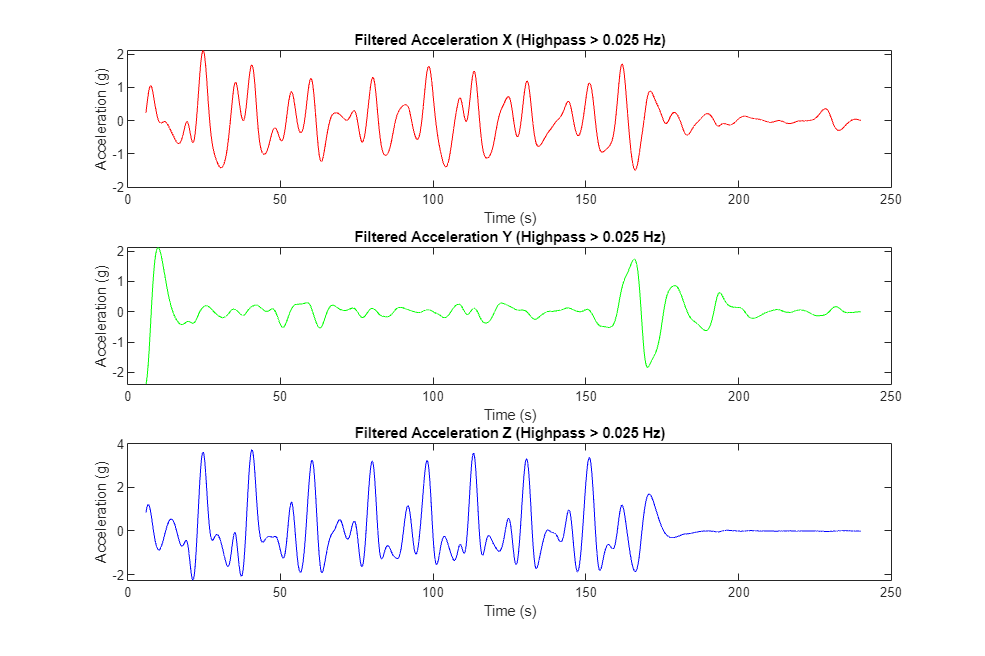

% -------------------------------------------------------------------------
% Filtrado adicional para remover frecuencias inferiores a 0.025 Hz
cutoffFrequency = 0.025; % Frecuencia de corte (Hz)
[bHigh, aHigh] = butter(2, (2 * cutoffFrequency) / nyquistFreq, 'high');

% Aplicar el segundo filtro pasaaltos
accX_filtered = filtfilt(bHigh, aHigh, accX_filtered);
accY_filtered = filtfilt(bHigh, aHigh, accY_filtered);
accZ_filtered = filtfilt(bHigh, aHigh, accZ_filtered);

% Graficar las señales después del segundo filtrado
figure('Position', [40 70 900 600], 'NumberTitle', 'off', 'Name', 'Filtered Accelerations After Highpass');
subplot(3,1,1);
plot(time, accX_filtered, 'r');
title('Filtered Acceleration X (Highpass > 0.025 Hz)');
xlabel('Time (s)');
ylabel('Acceleration (g)');

subplot(3,1,2);
plot(time, accY_filtered, 'g');
title('Filtered Acceleration Y (Highpass > 0.025 Hz)');
xlabel('Time (s)');
ylabel('Acceleration (g)');

subplot(3,1,3);
plot(time, accZ_filtered, 'b');
title('Filtered Acceleration Z (Highpass > 0.025 Hz)');
xlabel('Time (s)');
ylabel('Acceleration (g)');

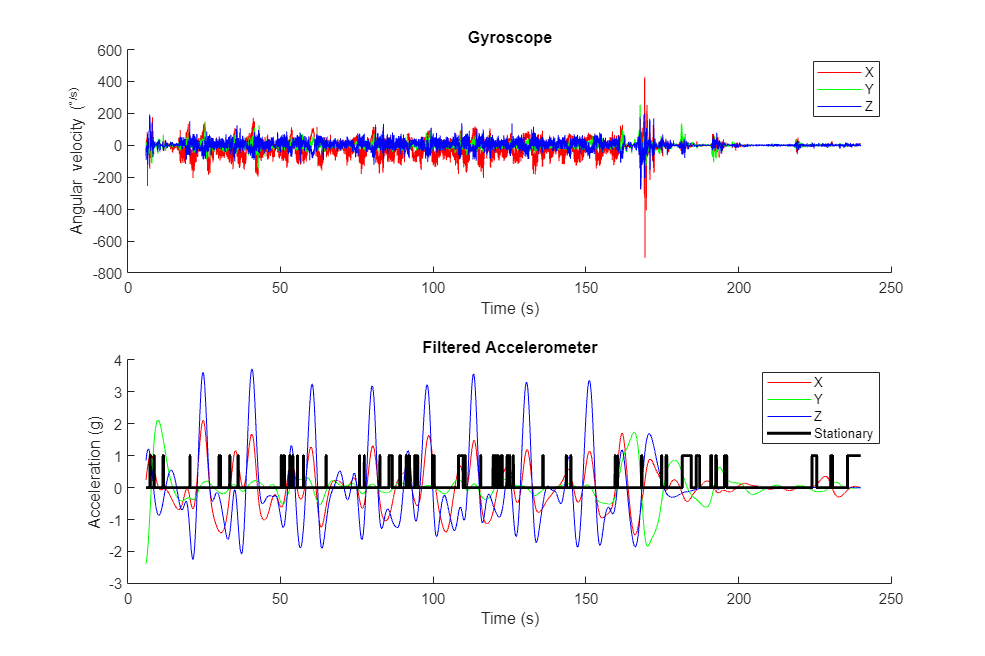




% -------------------------------------------------------------------------
% Detección de periodos estacionarios
acc_mag = sqrt(accX_filtered.*accX_filtered + accY_filtered.*accY_filtered + accZ_filtered.*accZ_filtered); % Magnitud del acelerómetro.
[b, a] = butter(1, (2*0.001)/(1/samplePeriod), 'high'); % Filtro pasa-alto.
acc_magFilt = filtfilt(b, a, acc_mag); % Aplica filtro.
acc_magFilt = abs(acc_magFilt); % Valor absoluto.
[b, a] = butter(1, (2*5)/(1/samplePeriod), 'low'); % Filtro pasa-bajo.
acc_magFilt = filtfilt(b, a, acc_magFilt); % Aplica filtro.
stationary = acc_magFilt < 0.05; % Detecta periodos estacionarios.

% -------------------------------------------------------------------------
% Gráfica de datos brutos del sensor y periodos estacionarios

figure('Position', [9 39 900 600], 'NumberTitle', 'off', 'Name', 'Sensor Data'); % Crea una figura para visualizar los datos.
ax(1) = subplot(2,1,1); % Crea el primer subplot para los datos del giroscopio.
    hold on;
    plot(time, gyrX, 'r'); % Traza el giroscopio en el eje X en rojo.
    plot(time, gyrY, 'g'); % Traza el giroscopio en el eje Y en verde.
    plot(time, gyrZ, 'b'); % Traza el giroscopio en el eje Z en azul.
    title('Gyroscope'); % Título del gráfico.
    xlabel('Time (s)'); % Etiqueta del eje X.
    ylabel('Angular velocity (^°/s)'); % Etiqueta del eje Y.
    legend('X', 'Y', 'Z'); % Leyenda.
    hold off;

ax(2) = subplot(2,1,2); % Crea el segundo subplot para los datos del acelerómetro.
    hold on;
    plot(time, accX_filtered, 'r'); % Traza el acelerómetro filtrado en el eje X en rojo.
    plot(time, accY_filtered, 'g'); % Traza el acelerómetro filtrado en el eje Y en verde.
    plot(time, accZ_filtered, 'b'); % Traza el acelerómetro filtrado en el eje Z en azul.
    plot(time, stationary, 'k', 'LineWidth', 2); % Traza los periodos estacionarios en negro.
    title('Filtered Accelerometer'); % Título del gráfico.
    xlabel('Time (s)'); % Etiqueta del eje X.
    ylabel('Acceleration (g)'); % Etiqueta del eje Y.
    legend('X', 'Y', 'Z', 'Stationary'); % Leyenda.
    hold off;

linkaxes(ax,'x'); % Vincula los ejes X de los dos subplots.

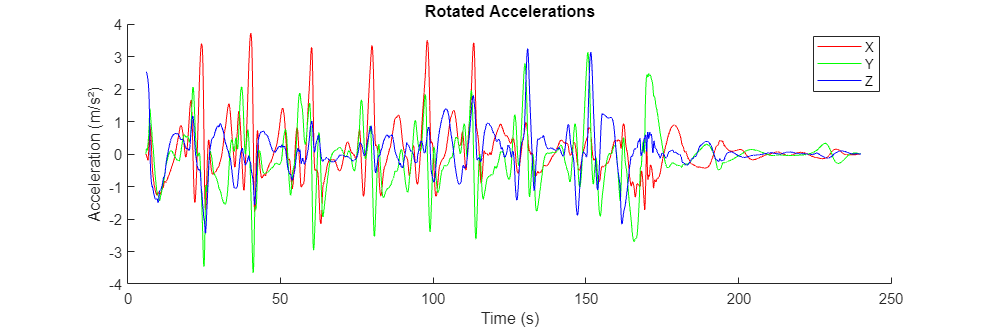


% -------------------------------------------------------------------------
% Cálculo de la orientación

quat = zeros(length(time), 4); % Inicializa la matriz de cuaterniones.
AHRSalgorithm = AHRS('SamplePeriod', samplePeriod, 'Kp', 1, 'KpInit', 1); % Configura el algoritmo AHRS con parámetros iniciales.

% Convergencia inicial
initPeriod = 2; % Periodo inicial para estabilizar el algoritmo.
indexSel = 1 : find(time >= initPeriod, 1); % Selección de índices para el periodo inicial.
for i = 1:2000
    AHRSalgorithm.UpdateIMU([0 0 0], [mean(accX_filtered(indexSel)) mean(accY_filtered(indexSel)) mean(accZ_filtered(indexSel))]); % Actualiza el algoritmo usando valores promedio iniciales.
end

% Calcular orientación para todos los datos
for t = 1:length(time)
    if(stationary(t))
        AHRSalgorithm.Kp = 0.5; % Reduce el factor de ganancia durante periodos estacionarios.
    else
        AHRSalgorithm.Kp = 0; % Elimina la ganancia durante movimientos.
    end
    AHRSalgorithm.UpdateIMU(deg2rad([gyrX_filtered(t) gyrY_filtered(t) gyrZ_filtered(t)]), [accX_filtered(t) accY_filtered(t) accZ_filtered(t)]); % Actualiza el cuaternio con datos del giroscopio y acelerómetro.
    quat(t,:) = AHRSalgorithm.Quaternion; % Almacena el cuaternio calculado.
end

% -------------------------------------------------------------------------
% Cálculo de aceleraciones translacionales

acc = quaternRotate([accX_filtered accY_filtered accZ_filtered], quaternConj(quat)); % Rota las aceleraciones del marco del cuerpo al marco terrestre.
%acc = acc * 9.81; % Convierte las aceleraciones a unidades de m/s².

% Gráfica de aceleraciones rotadas para depuración
figure('Position', [9 39 900 300], 'NumberTitle', 'off', 'Name', 'Rotated Accelerations');
hold on;
plot(time, acc(:,1), 'r'); % Eje X
plot(time, acc(:,2), 'g'); % Eje Y
plot(time, acc(:,3), 'b'); % Eje Z
title('Rotated Accelerations'); % Título del gráfico.
xlabel('Time (s)'); % Etiqueta del eje X.
ylabel('Acceleration (m/s²)'); % Etiqueta del eje Y.
legend('X', 'Y', 'Z'); % Leyenda.
hold off;


% -------------------------------------------------------------------------
% Cálculo de velocidades translacionales

acc(:,3) = acc(:,3) - 9.81; % Compensa la gravedad en el eje Z.

% Integración para calcular la velocidad
vel = zeros(size(acc)); % Inicializa la matriz de velocidades.
for t = 2:length(vel)
    vel(t,:) = vel(t-1,:) + acc(t,:) * samplePeriod; % Integra la aceleración para obtener la velocidad.
    if(stationary(t) == 1)
        vel(t,:) = [0 0 0]; % Fuerza la velocidad a cero durante periodos estacionarios.
    end
end

% Compensación de deriva integral durante movimientos
velDrift = zeros(size(vel)); % Inicializa la matriz de deriva.
stationaryStart = find([0; diff(stationary)] == -1); % Encuentra inicios de periodos no estacionarios.
stationaryEnd = find([0; diff(stationary)] == 1); % Encuentra finales de periodos no estacionarios.
numel(stationaryEnd)

ans = 50

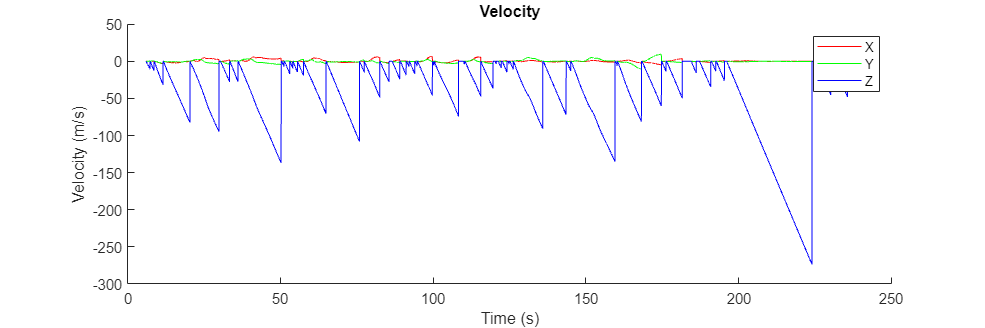

for i = 1:numel(stationaryEnd)-1
    driftRate = vel(stationaryEnd(i)-1, :) / (stationaryEnd(i) - stationaryStart(i)); % Calcula la tasa de deriva.
    enum = 1:(stationaryEnd(i) - stationaryStart(i));
    drift = [enum'*driftRate(1) enum'*driftRate(2) enum'*driftRate(3)];
    velDrift(stationaryStart(i):stationaryEnd(i)-1, :) = drift; % Aplica la corrección de deriva.
end

vel = vel - velDrift; % Elimina la deriva integral.

% Gráfica de velocidades translacionales
figure('Position', [9 39 900 300], 'NumberTitle', 'off', 'Name', 'Velocity');
hold on;
plot(time, vel(:,1), 'r'); % Velocidad en el eje X.
plot(time, vel(:,2), 'g'); % Velocidad en el eje Y.
plot(time, vel(:,3), 'b'); % Velocidad en el eje Z.
title('Velocity'); % Título del gráfico.
xlabel('Time (s)'); % Etiqueta del eje X.
ylabel('Velocity (m/s)'); % Etiqueta del eje Y.
legend('X', 'Y', 'Z'); % Leyenda.
hold off;

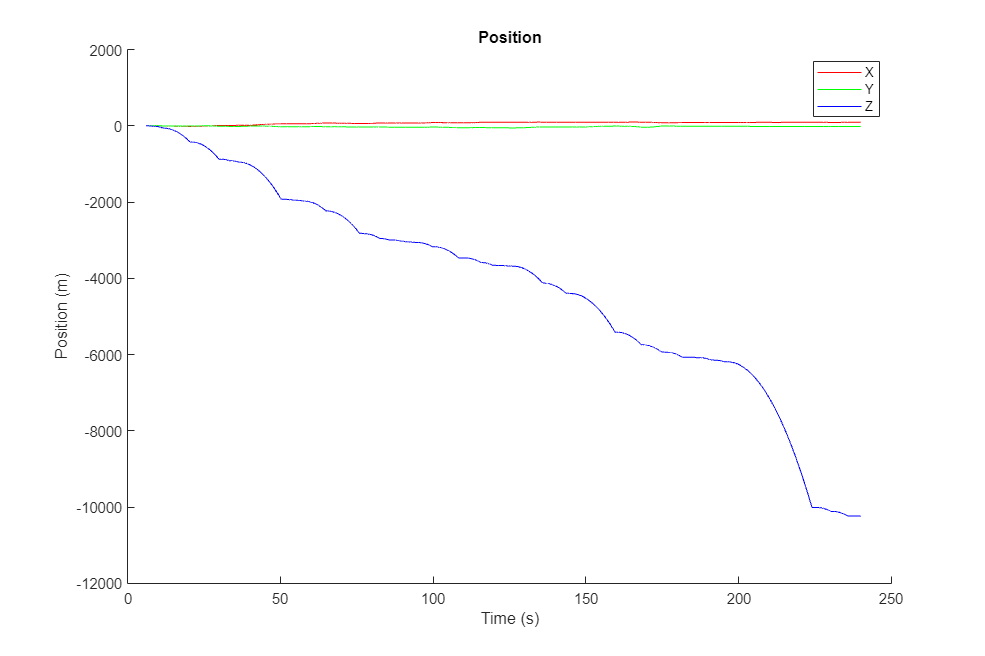


% -------------------------------------------------------------------------
% Cálculo de posiciones translacionales

pos = zeros(size(vel)); % Inicializa la matriz de posiciones.
for t = 2:length(pos)
    pos(t,:) = pos(t-1,:) + vel(t,:) * samplePeriod; % Integra la velocidad para obtener la posición.
end

% Gráfica de posiciones translacionales
figure('Position', [9 39 900 600], 'NumberTitle', 'off', 'Name', 'Position');
hold on;
plot(time, pos(:,1), 'r'); % Posición en el eje X.
plot(time, pos(:,2), 'g'); % Posición en el eje Y.
plot(time, pos(:,3), 'b'); % Posición en el eje Z.
title('Position'); % Título del gráfico.
xlabel('Time (s)'); % Etiqueta del eje X.
ylabel('Position (m)'); % Etiqueta del eje Y.
legend('X', 'Y', 'Z'); % Leyenda.
hold off;


% -------------------------------------------------------------------------
% Trajectory 3D Plot
% 
% posPlot = pos;
% quatPlot = quat;
% 
% % Extend final sample to delay end of animation
% extraTime = 20;
% onesVector = ones(extraTime*(1/samplePeriod), 1);
% posPlot = [posPlot; [posPlot(end, 1)*onesVector, posPlot(end, 2)*onesVector, posPlot(end, 3)*onesVector]];
% quatPlot = [quatPlot; [quatPlot(end, 1)*onesVector, quatPlot(end, 2)*onesVector, quatPlot(end, 3)*onesVector, quatPlot(end, 4)*onesVector]];
% 
% % Create 6 DOF animation
% SamplePlotFreq = 4;
% Spin = 120;
% SixDofAnimation(posPlot, quatern2rotMat(quatPlot), ...
%                 'SamplePlotFreq', SamplePlotFreq, 'Trail', 'All', ...
%                 'Position', [9 39 1280 768], 'View', [(100:(Spin/(length(posPlot)-1)):(100+Spin))', 10*ones(length(posPlot), 1)], ...
%                 'AxisLength', 0.1, 'ShowArrowHead', false, ...
%                 'Xlabel', 'X (m)', 'Ylabel', 'Y (m)', 'Zlabel', 'Z (m)', 'ShowLegend', false, ...
%                 'CreateAVI', false, 'AVIfileNameEnum', false, 'AVIfps', ((1/samplePeriod) / SamplePlotFreq));

